## Lab #3:  Asking a statistical question

## Problem 1

For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12  Kelvin to within the 0.4 degree precision of the thermometry and the  thermal control system (standard deviation). However, there are times  when the thermal control system misbehaved and the temperature was not  near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the  temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and  we just had a wonky reading, in an abundance of caution we want to throw those values out too.

Start by simulating 100k 'good' data points assuming Gaussian  fluctations, and because we are playing god adding the following 'bad'  datapoints:  {10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7}


% I set the rng seed here so that the values generated would be the same
% everytime it was run. The advantage being I dont have to manually adjust
% my truth table everytime I run the code in the mlx file...
rng(1)
size_sample = 100000;
sample_mean = 12;
sample_standard_dev = 0.4;
gaussian_sample = normrnd(sample_mean, sample_standard_dev, 1, size_sample);
bad_datapoints = [10, 10.3, 2.1, 0, 0, 15.6, 22.3, 12.7];
num_bad_points = length(bad_datapoints);
full_sample = [gaussian_sample, bad_datapoints];

A) So our goal is to identify bad data and throw it out.

1. Start by exploring the data you have created with appropriate plots

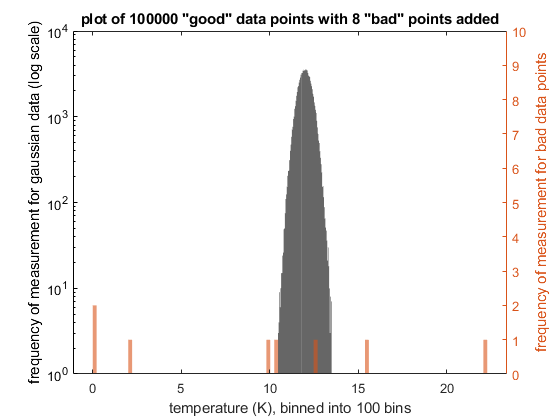

numbins = 100;
figure

h = histogram(gaussian_sample,numbins, 'DisplayStyle', 'bar', 'EdgeColor', 'none', 'LineWidth', 3);
set(gca, 'YScale', 'log')
ylabel('frequency of measurement for gaussian data (log scale)')
hold on
yyaxis right
ylim([0,10])
histogram(bad_datapoints,numbins, 'DisplayStyle', 'bar', 'EdgeColor', 'none', 'LineWidth', 3);
title(['plot of ' num2str(size_sample) ' "good" data points with ' num2str(num_bad_points) ' "bad" points added'])
xlabel(['temperature (K), binned into ' num2str(numbins) ' bins'])
ylabel('frequency of measurement for bad data points')

2. State the statistical question in words. Be very clear, and describe why you have chosen this statistical question.

The question we are trying to answer is: is the temperature measurement far from the mean? To do so, I will unilaterally ignore data points taken when they fall more than 1.5 standard deviations from the mean. In otherwords, I will say that every temperature datapoint outside of the range [11.4, 12.6] will be considered a bad data point. This will end up throwing out many points that were actually acceptably close to 12 (and only measured as further from 12 due to instrument error), but it is more important to discard bad data. In a real experiment, we would have to balance the error introduced if a bad data point isn't labeled as bad compared to the additional operational and time cost for taking extra data to compensate for the data we threw out.

3. Restate your question in math. Be very clear.

The version of the test I have constructed ask: assuming this data point comes from the expected Gaussian distribution of $\mathcal{N}(12 \text{ K}, (0.4 \text{ K})^2)$, if the probability that a point that far (or further) from the mean is sampled from the expected Gaussian distribution is less than 0.1336 (calcualted below), discard that point.

cut_off_std = 1.5;
cut_off_prob = 1- (normcdf(cut_off_std) - normcdf(-cut_off_std))

cut_off_prob = 0.1336

4. Apply your statistical test and construct a truth table.

dist_in_std_good_data = abs((gaussian_sample - sample_mean)/sample_standard_dev);
dist_in_std_bad_data = abs((bad_datapoints - sample_mean)/sample_standard_dev);

prob_at_least_that_far_good_data = 1 - ...
    (normcdf(dist_in_std_good_data) - normcdf(-dist_in_std_good_data));
prob_at_least_that_far_bad_data = 1- ...
    (normcdf(dist_in_std_bad_data) - normcdf(-dist_in_std_bad_data));

discarded_indexes_from_good_data = ...
    find(prob_at_least_that_far_good_data < cut_off_prob);

discarded_indexes_from_bad_data = ...
    find(prob_at_least_that_far_bad_data < cut_off_prob);


num_discard_from_good_data = length(discarded_indexes_from_good_data)

num_discard_from_good_data = 13430

num_kept_from_good_data = ...
    length(gaussian_sample) - num_discard_from_good_data

num_kept_from_good_data = 86570


num_discard_from_bad_data = length(discarded_indexes_from_bad_data)

num_discard_from_bad_data = 8

num_kept_from_bad_data = ...
    length(bad_datapoints) - num_discard_from_bad_data

num_kept_from_bad_data = 0

**                                   True T              Bad T                    **

Your Test Good            86570               0

Your Test Bad              13430               8

The idea is how often you kept the known good data (True T & Your Test Good), how often you correctly discarded bad data (Bad T &  Your Test Bad), and how often mistakes were made of either omission or  commission (off diagonals).

B) How does the number of omissions, where you threw out good data,  depend on the statistical threshold you chose and is it a predictable  quantity?

Because I constructed my test based on the probability relative to the probability of being at least 1.5 standard deviations from the mean, we can simply multiply the probability of a good data point coming from that far (or further) from the mean by the number of samples. Because our cut-off probability was 0.1336, we can multiply that by the sample size of 100k to get the estimated 13.36k "good" data points thrown out. This is close to the actual number of 13430. Adjusting the threshold probability would  adjust the expected number of good data points being thrown out but simply multiplying the new threshold probability by the number of points in the sample. 

C) Are there mistakes of commission (bad data getting in)? If yes,  are they avoidable and how do they depend on your statistical threshold? 

With this test, there are no mistakes of commission. This would happen if I set the cutoff probability at a lower value, as this would let in more extreme data points. If I had mistakes of commission,  increasing the cutoff probability reduces the number of extreme data points let in, and would increase the probability of throwing out a "bad" measurement. It would also throw out more "good" datapoints.

## Problem 2

In this example we will be looking for asteroids. If we look at the  alignment of stars on subsequent images, they don't perfectly align due  to atmospheric and instrumental effects (even ignoring proper motion).  The resulting distribution is two dimensional, and for this lab let's  assume it is a 2D Gaussian with 1 arcsecond RMS. 

If I have a potential asteroid, it will have some true movement  between the images. We would like a '5 sigma' detection of movement.  What is that distance in arcseconds?

1. What is the question in words?

Suppose we are tracking some object in the night sky. The question we are asking is: what is the minimum distance between successive location measurements of that object such that the probability that a distance that much or greater caused only by the expected uncertainty in the positional measurement is as likely as the probabalistic inverse (one minus) the cumulative probability of a Gaussian up to 5 standard deviations to the right of it's mean. 

In other words, what is the minimum distance between successive location measurements that corresponds to the probability of measuring that distance or greater is ~1 in 3.5 million from just the expected variation in positional measurement. 

prob_5sigma = 1 - normcdf(5)

prob_5sigma = 2.8665e-07

2. What is the question in math? [Hint: Come up with an analytic description of your pdf(). The Blue Book may be helpful here.]

In math, we are looking at the probability distribution of the magnitude of the vectors that describe the motion between subsequent position measurements. Because the position along each axis in this 2D image is described by an independent Gaussian distribution, the difference vector is also. Recall that the sum of two Gaussian distributions was itself Gaussian. Specifically, if $X \sim \mathcal{N}(\mu_x, \sigma_x^2)$ and $Y \sim \mathcal{N}(\mu_y, \sigma_y^2)$ then $Z = X + Y \sim \mathcal{N}(\mu_x + \mu_y, \sigma_x^2 + \sigma_y^2)$. When looking at a difference of Gaussians we simply get: $Z = X - Y \sim \mathcal{N}(\mu_x - \mu_y, \sigma_x^2 + \sigma_y^2)$. Our positional distributions have mean 0 (no variation from the "correct" location) and variance of 1 arcsecond each. So the difference vector, multivariate distribution has the form: $\Delta = X_{\Delta} \hat{i} + Y_{\Delta} \hat{j}$ where each component is Gaussian and retains a mean of 0 (0-0 = 0) but has a variance of 2 arcseconds. Now, we want the distribution of the magnitude of these difference vectors. From hw3, we know that the euclidean 2 norm of 2 Gaussian distributions with equal variance is a Rayleigh distribution with scale parameter equal to their standard deviation. As a consequence, we know that the pdf for the distribution of distances between successive frames due to only the expected uncertainty in the measurement is a Rayleigh distribution with scale parameter of $\sqrt{2}$ arcseconds:


$$pdf(|\vec{\Delta}| = r) = \frac{r}{2} e^{-r^2/4}$$


where $r$ is measured in units of arcseconds, and the units of the pdf are inverse arcseconds. 

The question now becomes, what value of $R_{5 \text{ sigma}}$ is required such that the probability of pulling a value at least as large as $R_{5 \text{ sigma}}$ is equivalent to the probability of a 5-sigma event listed in part 1.

3. What distance in arcseconds represents a 5 sigma detection of motion?

Using raylinv(P, B) built in to matlab, we can find the value needed such that the cumulative probability is equivalent to the 5 sigma case we want.

distance_for_5_sigma = raylinv(1-prob_5sigma, sqrt(2))

distance_for_5_sigma = 7.7627

Thus the minimum distance between consecutive images of the object required to be a "5-sigma" detection of motion is 7.7627 arc seconds. Note that this distance would only be a 5-sigma detection of motion if we only took two pictures. I suppose that we could say if we had taken a series of images over a long interval, we could look at just the first and last image in that interval and ask the question: did it start and end at the same place. A 5-sigma detection of motion with that question would be the same as only measuring it twice. 

## Problem 3

Assume in a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute (arrivals are random in time). If we  can observe where the moon is for 8 hours per night (not too close to  the horizon) and we observe for 15 days and see 6800 cosmic rays, what  is the signficance of our moon shadow detection?

1. What is the question in words?

 In words, we are asking is the observation of the 6800 (or fewer) cosmic rays from the direction of the moon over 15 days (8 hours per day) unlikely enough assuming an average of 1 cosmic ray per minute, that we can reject this assumption, and conclude the average number of cosmic rays per minute measured from the direction of the moon must be less than 1 per minute. The implication being that the moon is blocking cosmic rays. 

2. Translate the question to math, describing both the expected background pdf() and the integral you need to do.

A rate of 1 cosmic ray per minute with arrivals random in time is described by a Poisson distribution. As such, the discrete probability distribution for the number of cosmic rays coming from a single moon-size patch is a poisson distribution with rate of 1. We can use the fact that the sum of various Poisson distribution is simply a poisson distribution with the sum of the various rates (shown in lab 2 for 2 Poisson distributions, and generalized by the associative rule). Calculating the probability of measuring a value of 6800 or fewer simply comes down to a cumulative probability distribution of the possion with the new mean up to that value of 6800:

observed_rays = 6800;
num_days = 15;
hours_per_day = 8;
minutes_per_hour = 60;
rate_per_minute = 1;
num_intervals = num_days*hours_per_day*minutes_per_hour;
poisson_mean = num_intervals*rate_per_minute;
prob_of_measurement = poisscdf(observed_rays, poisson_mean)

prob_of_measurement = 1.0133e-06

3. Convert to sigma.

 Converting to a sigma just requires using norminv() on one minus the probability found in part 2:

sigma_val = norminv(1-prob_of_measurement)

sigma_val = 4.7507

So while the probability of measuring 6800 or fewer cosmic rays from the direction of the moon over the measurement period is very unlikely, this is not a 5-sigma detection of the moon's ability to block cosmic rays. 